% cleaning
clc
clear

% importing data
df1=readtable("..\data\experimental-data-1.csv")

df1 = 10×4 table
    dimension    value    uncertainty      uom  
    _________    _____    ___________    _______

     {'d1' }      55           1         {'CMT'}
     {'d2' }      60           1         {'CMT'}
     {'d3' }      65           1         {'CMT'}
     {'d4' }      70           1         {'CMT'}
     {'d5' }      75           1         {'CMT'}
     {'d6' }      80           1         {'CMT'}
     {'d7' }      85           1         {'CMT'}
     {'d8' }      90           1         {'CMT'}
     {'d9' }      95           1         {'CMT'}
     {'d10'}      98           1         {'CMT'}


df2=readtable("..\data\experimental-data-2.csv")

df2 = 1000×5 table
    event    distance    time    uncertainty      uom  
    _____    ________    ____    ___________    _______

      1      {'d10'}     819          1         {'C26'}
      2      {'d10'}     799          1         {'C26'}
      3      {'d10'}     818          1         {'C26'}
      4      {'d10'}     819          1         {'C26'}
      5      {'d10'}     815          1         {'C26'}
      6      {'d10'}     817          1         {'C26'}
      7      {'d10'}     818          1         {'C26'}
      8      {'d10'}     798          1         {'C26'}
      9      {'d10'}     819          1         {'C26'}
     10      {'d10'}     819          1         {'C26'}
     11      {'d10'}     819          1         {'C26'}
     12      {'d10'}     817          1         {'C26'}
     13      {'d10'}     8

tools=readtable("..\data\tools.csv")

tools = 2×3 table
             tool             uncertainty      uom  
    ______________________    ___________    _______

    {'sensore prossimità'}       0.001       {'SEC'}
    {'asta graduata'     }        0.01       {'MTR'}



% unique distance
hd=unique(df2.distance);
ld=length(hd);

% defining variable
l0=1;
g=9.8;
dg=0.1;

% creating empty array
tm=zeros(ld,1);     % tempi medi
dtm=zeros(ld,1);    % deviazione standard tempi
d=zeros(ld,1);      % distance from CM
dd=zeros(ld,1);     % delta distance
tt=zeros(ld,1);     % delta t
r=[0:0.0001:0.5]    % theoretical distance

r =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049



% multiply *2 and obtain T
for i=1:height(df2)
    df2.time(i)=df2.time(i)*2;
end


% core
for i=1:ld
    % calculating mean and converting ms2s
    tm(i)=mean(table2array(df2(df2.distance==string(hd(i)),"time"))./1000);
    % standard deviation on t
    dtm(i)=std(table2array(df2(df2.distance==string(hd(i)),"time"))./1000);
    % 
    d(i)=table2array(df1(df1.dimension==string(hd(i)),"value"));
    d(i)=d(i)-50;
    d(i)=d(i)/100; %cm2m
    dd(i)=df1.uncertainty(1)/100; 
end


tt =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% theoretical curve
tt=(2.*pi./sqrt(g)).*sqrt(((l0.^2)./(12.*r))+r);

% visualizing array
cat(2,string(hd),d,dd,tm,dtm)

ans = 10×5 string array
    "d1"     "0.05"    "0.01"    "3.1408"    "0.023539"
    "d10"    "0.48"    "0.01"    "1.6275"    "0.016542"
    "d2"     "0.1"     "0.01"    "2.0203"    "0.019995"
    "d3"     "0.15"    "0.01"    "1.7504"    "0.018007"
    "d4"     "0.2"     "0.01"    "1.5974"    "0.010466"
    "d5"     "0.25"    "0.01"    "1.5833"    "0.020015"
    "d6"     "0.3"     "0.01"    "1.5604"    "0.01231" 
    "d7"     "0.35"    "0.01"    "1.5321"    "0.019243"
    "d8"     "0.4"     "0.01"    "1.5712"    "0.019175"
    "d9"     "0.45"    "0.01"    "1.5939"    "0.010867"


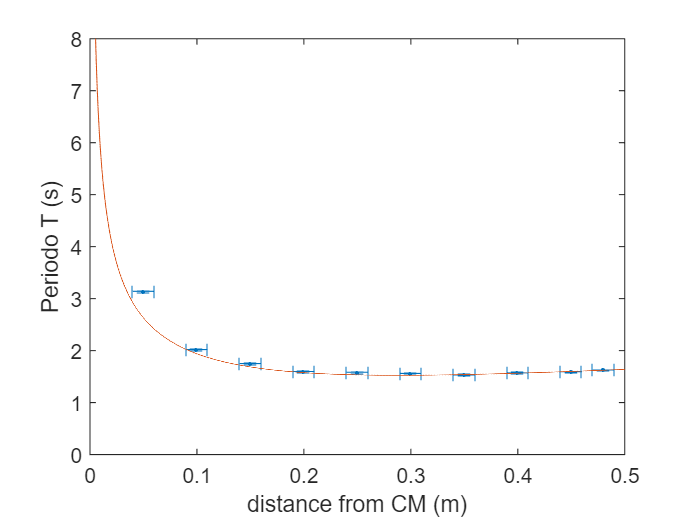


% plotting
errorbar(d,tm,dtm,dtm,dd,dd,'.')
xlabel('distance from CM (m)')
ylabel('Periodo T (s)')
xlim([0,0.5])
hold on
plot(r,tt)
hold off
ylim([0,8])





% histogram

% histogram(table2array(df2(df2.distance==string(hd(1)),"time")))
% histogram(table2array(df2(df2.distance==string(hd(2)),"time")))
% histogram(table2array(df2(df2.distance==string(hd(3)),"time")),20)
% histogram(table2array(df2(df2.distance==string(hd(4)),"time")))
% histogram(table2array(df2(df2.distance==string(hd(5)),"time")))
% histogram(table2array(df2(df2.distance==string(hd(6)),"time")))

%histogram(table2array(df2(df2.distance=="d3","time")),7)

% df2(df2.distance=="d1","time") % sostituire "d1" con gli elementi degli array
% mean(table2array(df2(df2.distance=="d1","time")))

% exporting csv
% writetable(array2table(namearray,'VariableNames',{'acceleration','uncertainty','uom','relative_error'}),'..\data\output-data-1.csv','Delimiter',',','Encoding','UTF-8')

% exporting img
% saveas(nameplot,'..\img\filename.png');

% exporting mlx2m
mlxloc = fullfile(pwd,'livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);